# `Lista 3`

`Hubert Jackowski`

## `Układ Lotki-Volterry`

`Równanie Lotki-Volterry to model układu dynamicznego opisujący wzajemną zależność  rozmiarów populacji drapieżników i ofiar. Został on zaproponowany niezależnie przez dwóch  badaczy Vito Volterrę w 1926 oraz Alfreda James Lotkę w 1920 roku. [1]`

#### `MODEL`

`Figure 1: Matematyczny model układu Lotki-Volterry`

`Gdzie: x - populacja ofiar, y - populacja drapieżników, t - czas, a - częstość narodzin ofiar, b - częstość umierania ofiar, c - częstość narodzin drapieżników, d - częstość umierania drapieżników.`

def lotkaVolterra(dt: float, t: float, x0: float, y0: float, a: float, b: float, c: float, d: float):
    def _lotkaVolterra(state):
        x, y = state

        dx = (a - b * y) * x
        dy = (c * x - d) * y

        return np.array([dx, dy])

    num_steps = int(t / dt)

    states = np.empty((num_steps + 1, 2))
    states[0] = (x0, y0)
    for i in range(num_steps):
        states[i + 1] = states[i] + _lotkaVolterra(states[i]) * dt
    return states

`Figure 2: Realizacja modelu Lotki-Volterry za pomocą metody Eulera w języku Python`

def lotkaVolterra(dt: float, t: float, x0: float, y0: float, a: float, b: float, c: float, d: float):
    def _lotkaVolterra(state, _t, _a, _b, _c, _d) -> list:
        x, y = state

        dx = (_a - _b * y) * x
        dy = (_c * x - _d) * y

        return [dx, dy]

    args = (x0, y0)
    time = np.arange(0.0, t, dt)
    param = (a, b, c, d)
    return odeint(_lotkaVolterra, args, time, param)

`Figure 3: Realizacja modelu Lotki-Volterry za pomocą metody scipy.integrate.odeint w języku Python`

## `Układ Lorenza`

`Układ Lorenza to model układu dynamicznego opisujący zjawisko konwekcji termicznej w atmosferze. Uwzględznia on lepkość ośrodka, jego przewodnictwo cieplne oraz rozmiary ośrodka, w którym odbywa się proces. Zaproponowany został przez Edwarda Lorenza w 1963 roku. [2]`

#### `MODEL`

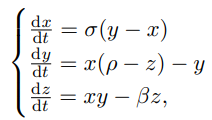

`Figure 4: Matematyczny model układu Lorentza`

`Gdzie:  σ – liczba Prandtla, charakteryzująca lepkość ośrodka; ρ – liczba Rayleigha, charakteryzująca przewodnictwo cieplne ośrodka; β – stała charakteryzująca rozmiary obszaru, w którym odbywa się przepływ konwekcyjny.`

def lorentz(dt: float, t: float, x0: float, y0: float, z0: float, sigma: float, beta: float, rho: float):
    def _lorentz(state):
        x, y, z = state
        dx = sigma * (y - x)
        dy = rho * x - y - x * z
        dz = x * y - beta * z
        return np.array([dx, dy, dz])

    num_steps = int(t / dt)

    states = np.empty((num_steps + 1, 3))
    states[0] = (x0, y0, z0)
    for i in range(num_steps):
        states[i + 1] = states[i] + _lorentz(states[i]) * dt
    return states


`Figure 5: Realizacja modelu Lorentza za pomocą metody Eulera w języku Python`

def lorentz(dt: float, t: float, x0: float, y0: float, z0: float, sigma: float, beta: float, rho: float):
    def _lorenz(state, _t, _sigma, _beta, _rho):
        x, y, z = state

        dx = _sigma * (y - x)
        dy = x * (_rho - z) - y
        dz = x * y - _beta * z

        return [dx, dy, dz]

    args = (x0, y0, z0)
    time = np.arange(0.0, t, dt)
    param = (sigma, beta, rho)
    return odeint(_lorenz, args, time, param)

`Figure 6: Realizacja modelu Lorentza za pomocą metody scipy.integrate.odeint w języku Python`

#### `OBSERWACJE`

`Poniżej przedstawione wykresy są wynikami symulacji dla wartości parametrów modelu Lotki-Volterry: {a = 1.2, b = 0.6, c = 0.3, d = 0.8, x(0) = 2, y(0) = 1} oraz modelu Układu Lorenza: {σ = 10, β = 8/3 i ρ = 28, x(0) = y(0) = z(0) = 1} dla czasu t ∈ [0, 25] i zmiennego dt ∈ {0.001, 0.01, 0.02}.`

`1. WYKRESY SYGNAŁÓW`

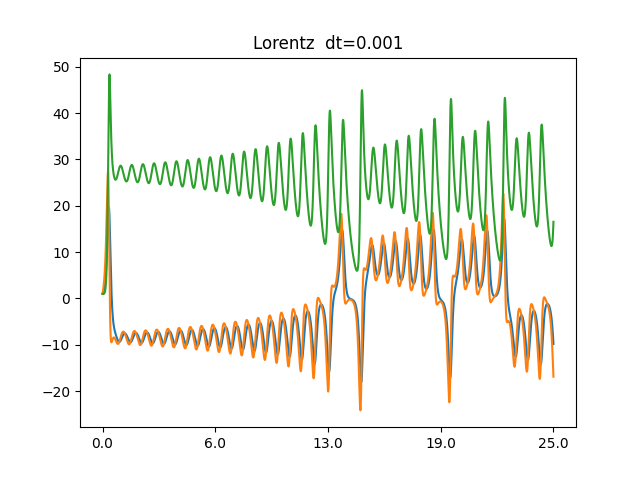

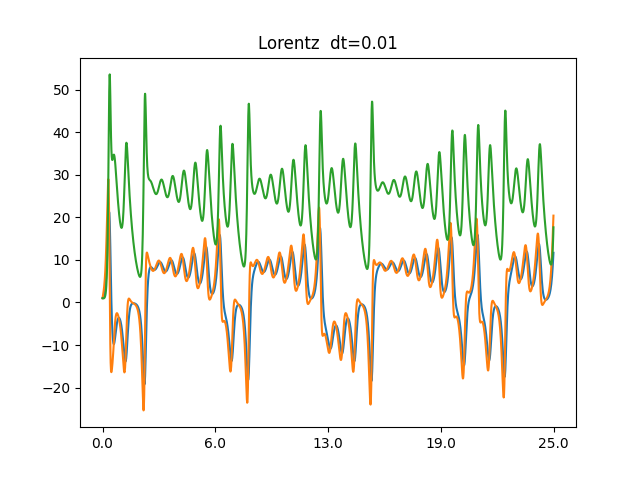

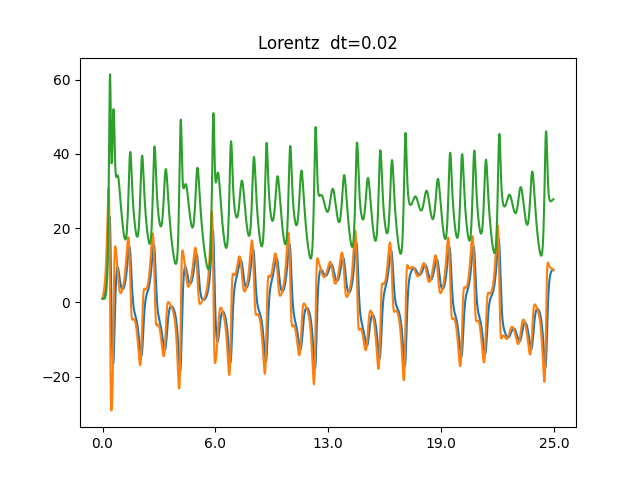

`Figure 7: Wykresy x(t) (niebieski), y(t) (pomarańczowy), z(x) (zielony) układu Lorentza metodą Eulera dla kroków dt = {0.001, 0.01, 0.02} przy stałych parametrach`

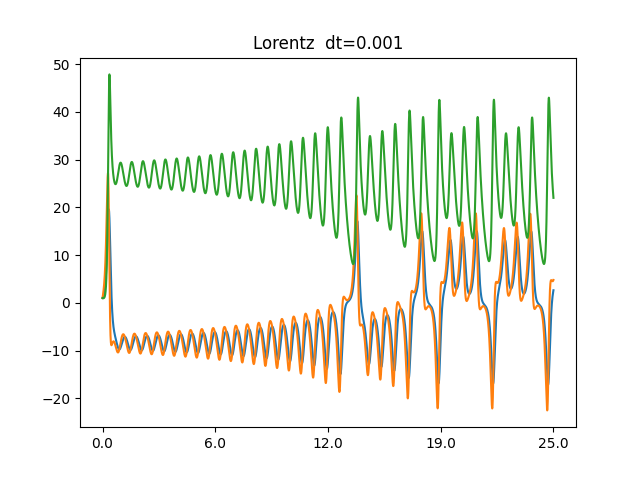

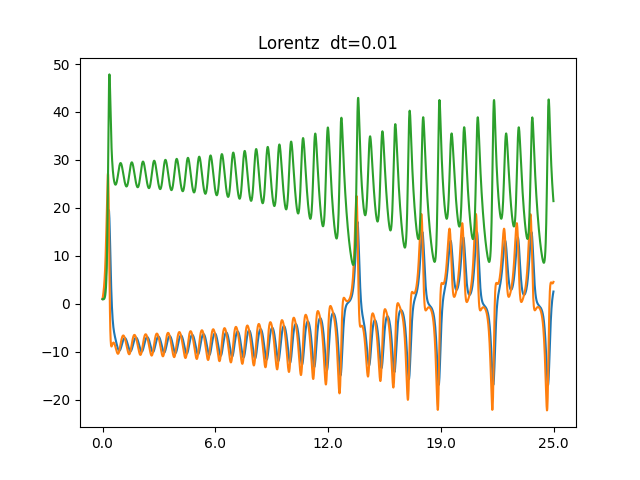

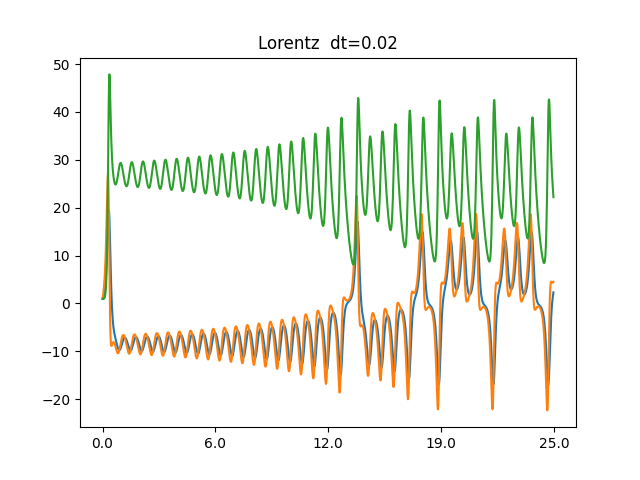

`Figure 8: Wykresy x(t) (niebieski), y(t) (pomarańczowy), z(x) (zielony) układu Lorentza metodą scipy.integrate.odeint dla kroków dt = {0.001, 0.01, 0.02} przy stałych parametrach`

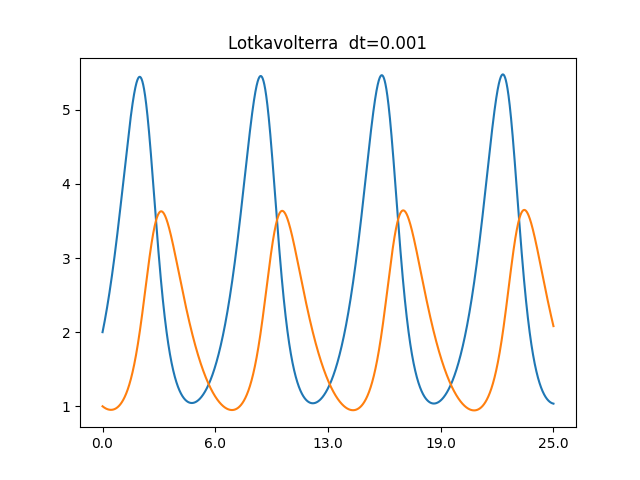

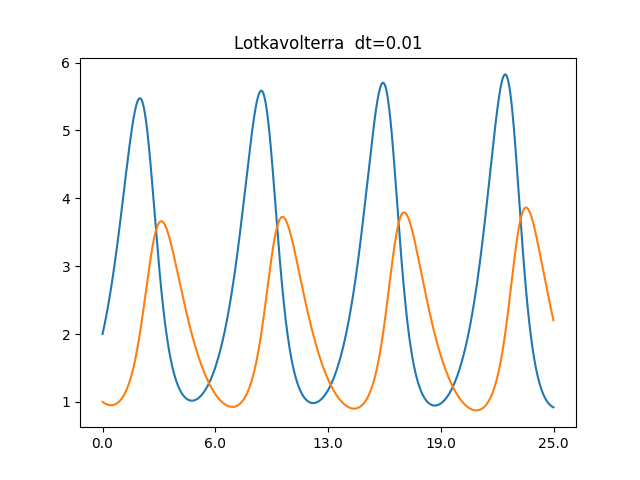

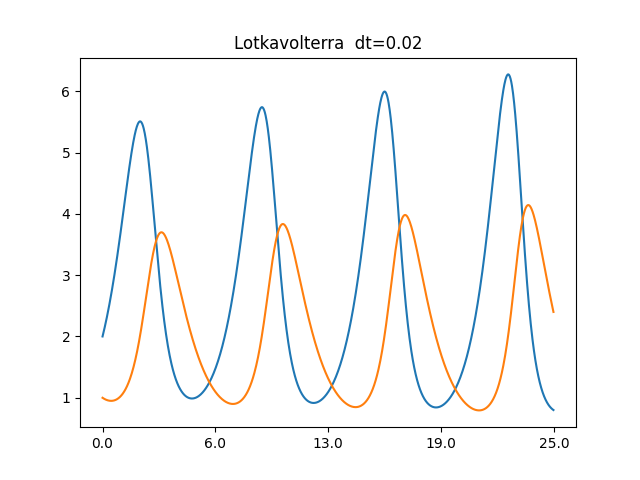

`Figure 9: Wykresy x(t) (niebieski), y(t) (pomarańczowy) układu Lotki-Volterry metodą Eulera dla kroków dt = {0.001, 0.01, 0.02} przy stałych parametrach`

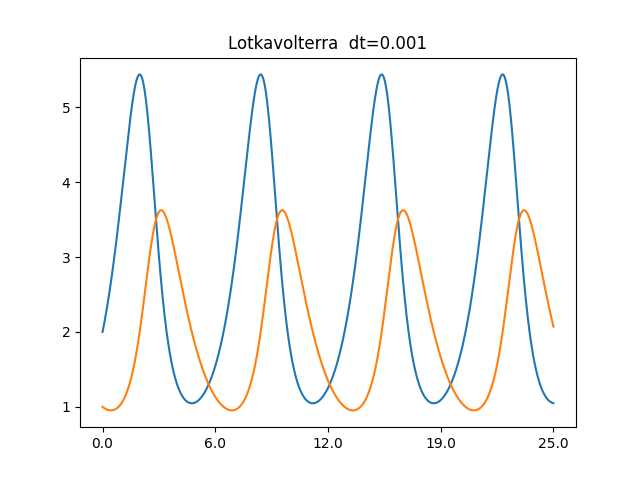

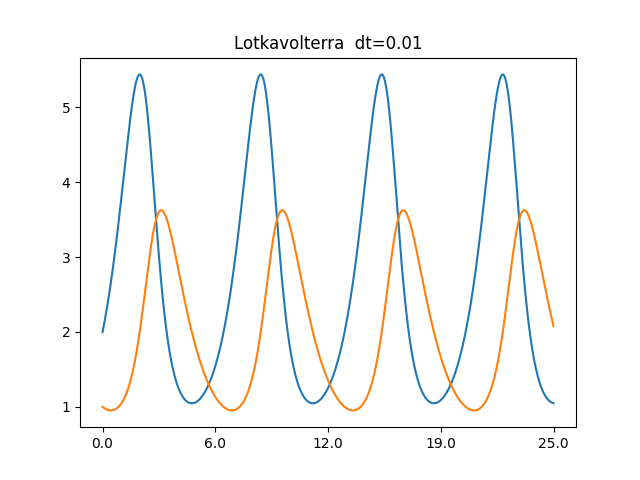

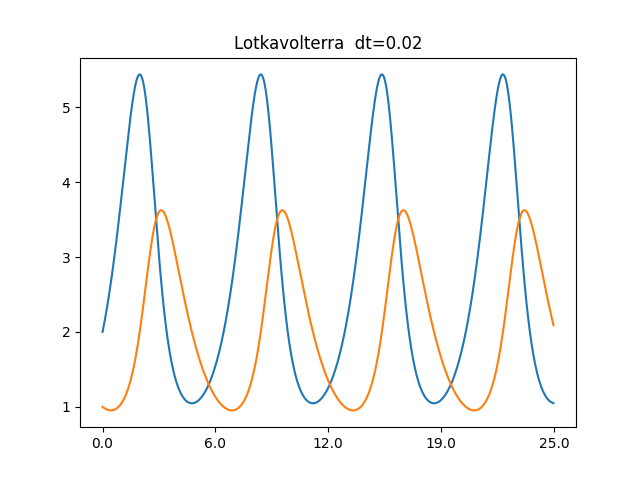

`Figure 10: Wykresy x(t) (niebieski), y(t) (pomarańczowy) układu Lotki-Volterry metodą scipy.integrate.odeint dla kroków dt = {0.001, 0.01, 0.02} przy stałych parametrach`

`2. WYKRESY ZALEŻNOŚCI`

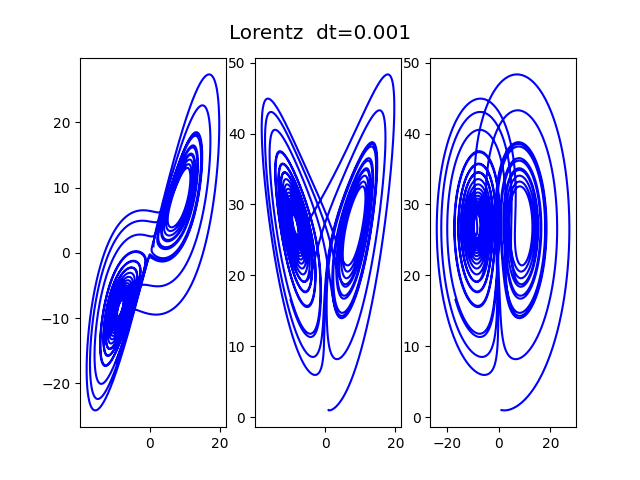

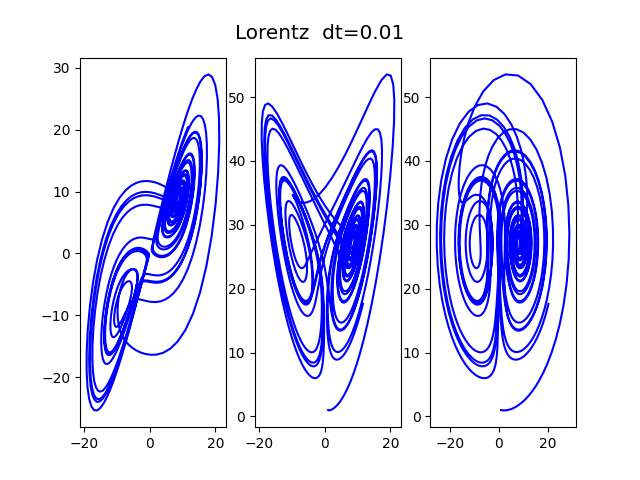

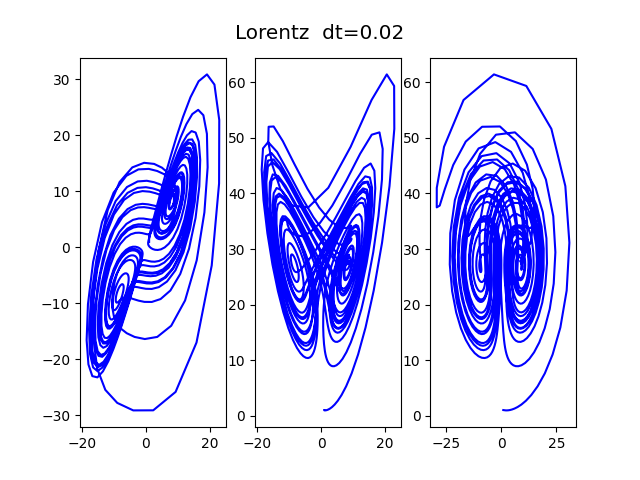

`Figure 11: Wykresy y(x), z(y), z(x)  układu Lorentza metodą Eulera dla kroków dt = {0.001, 0.01, 0.02} przy stałych parametrach`

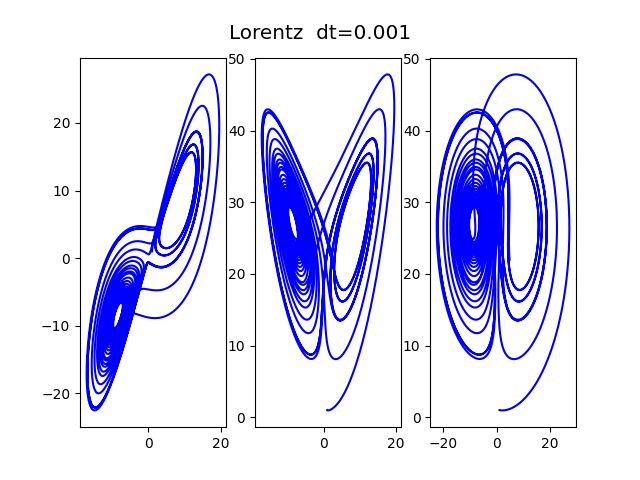

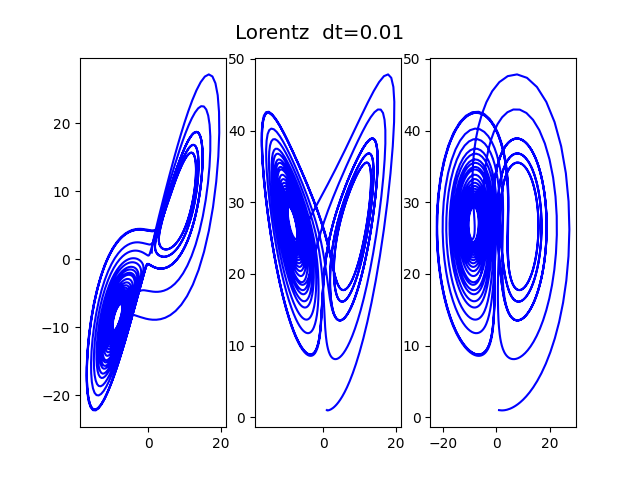

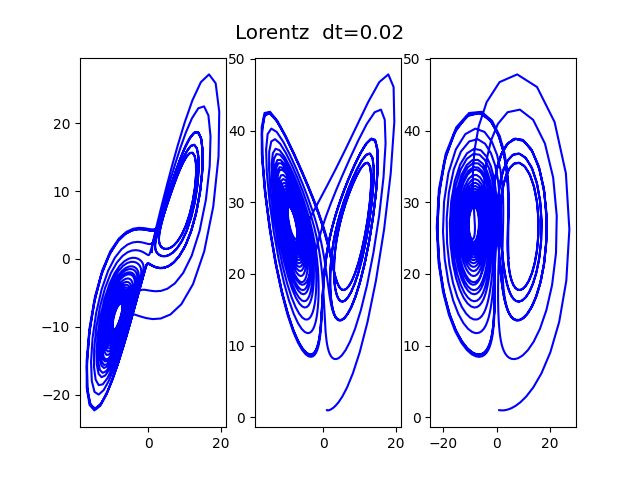

`Figure 12: Wykresy y(x), z(y), z(x)  układu Lorentza metodą scipy.integrate.odeint dla kroków dt = {0.001, 0.01, 0.02} przy stałych parametrach`

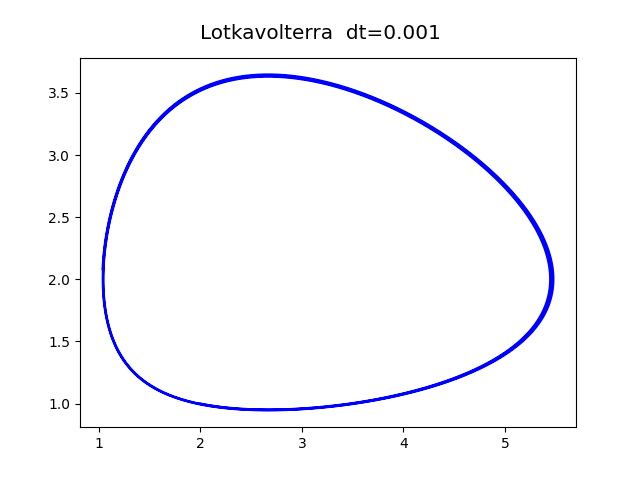

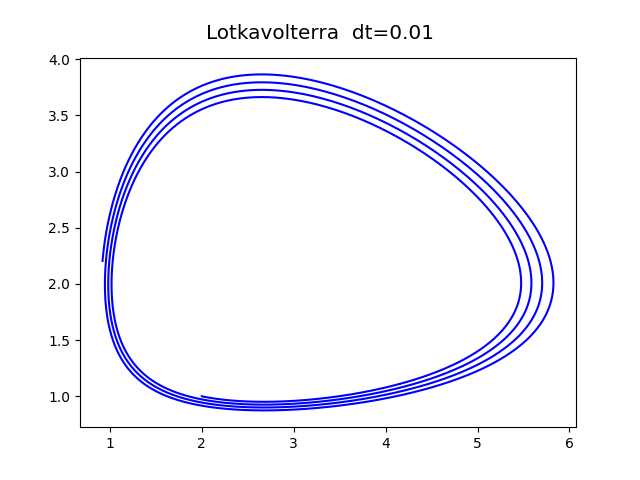

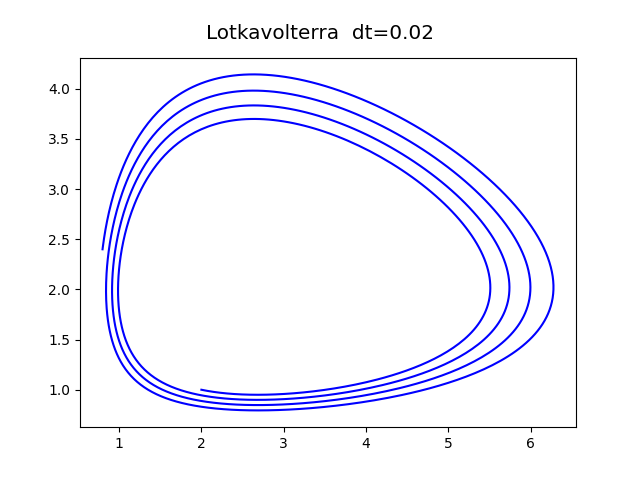

`Figure 13: Wykresy y(x) układu Lotki-Volterry metodą Eulera dla kroków dt = {0.001, 0.01, 0.02} przy stałych parametrach`

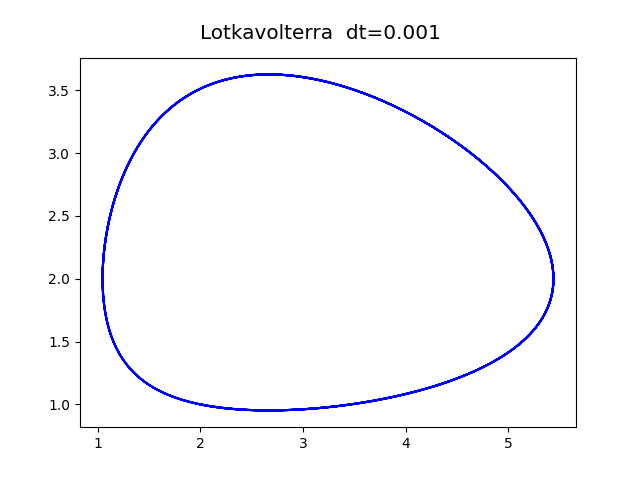

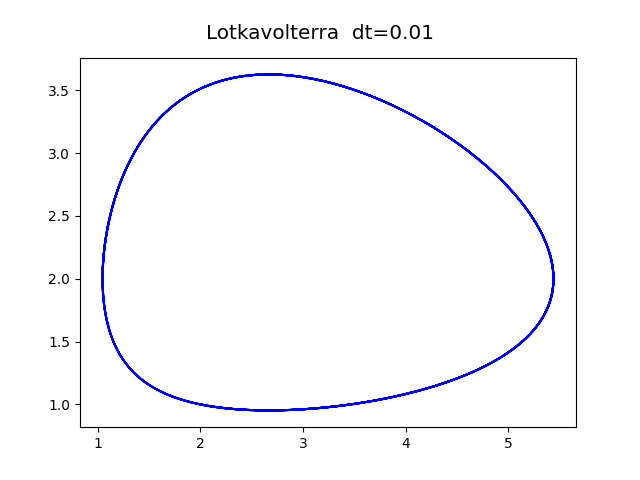

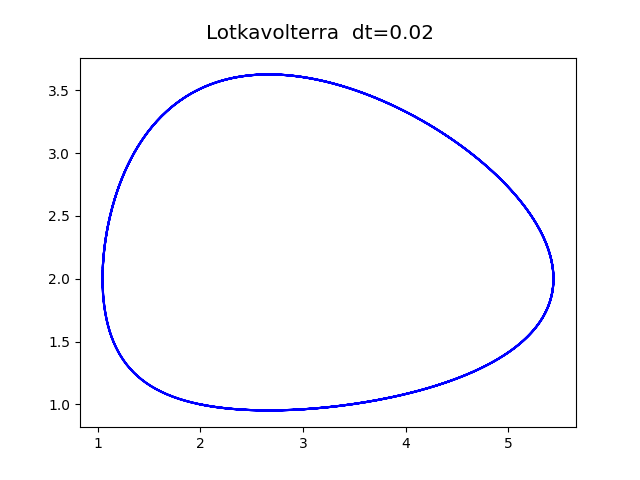

`Figure 14: Wykresy y(x) układu Lotki-Volterry metodą scipy.integrate.odeint dla kroków dt = {0.001, 0.01, 0.02} przy stałych parametrach`

`3. WYKRESY ZALEŻNOŚCI W PRZESTRZENI`

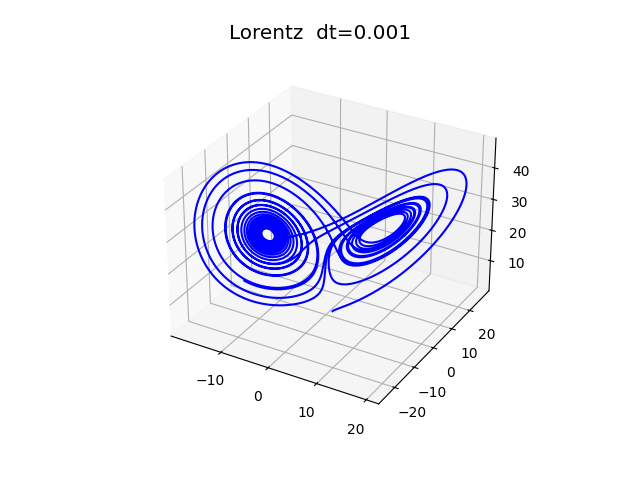

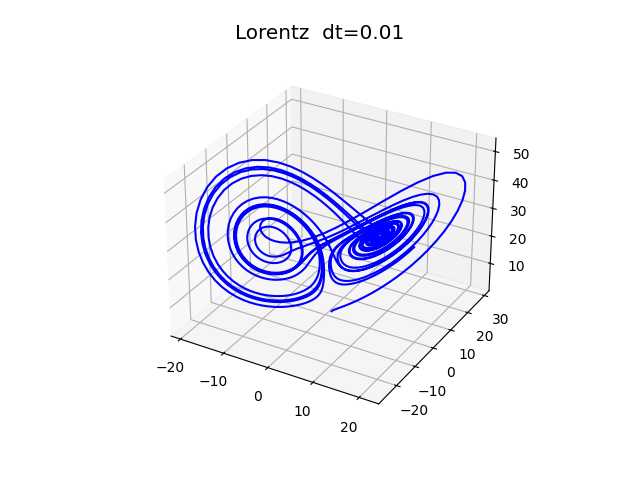

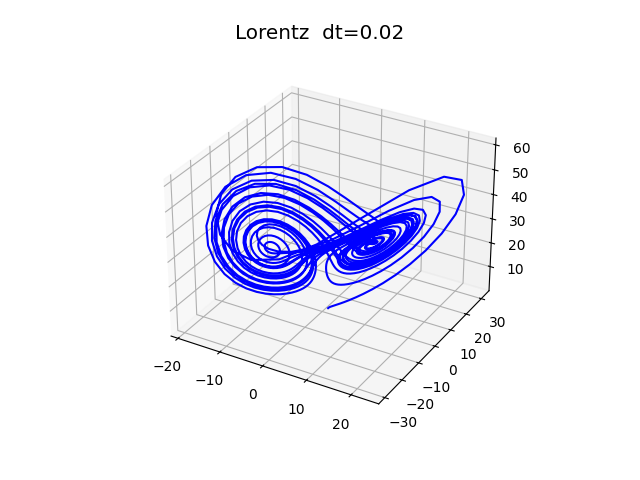

`Figure 15: Wykres z(x,y) układu Lorenza metodą Eulera dla kroków dt = {0.001, 0.01, 0.02} przy stałych parametrach`

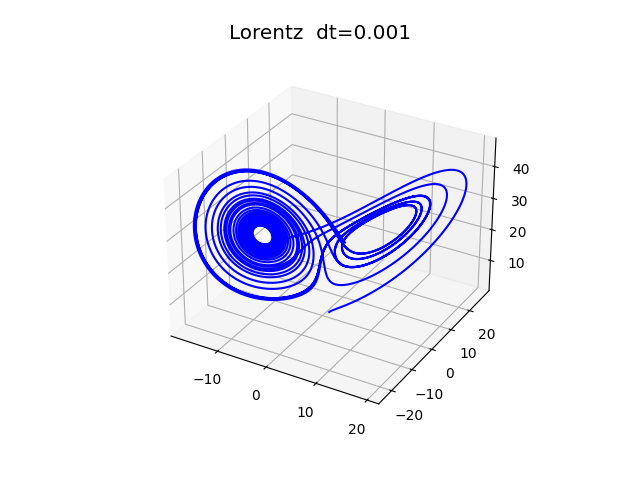

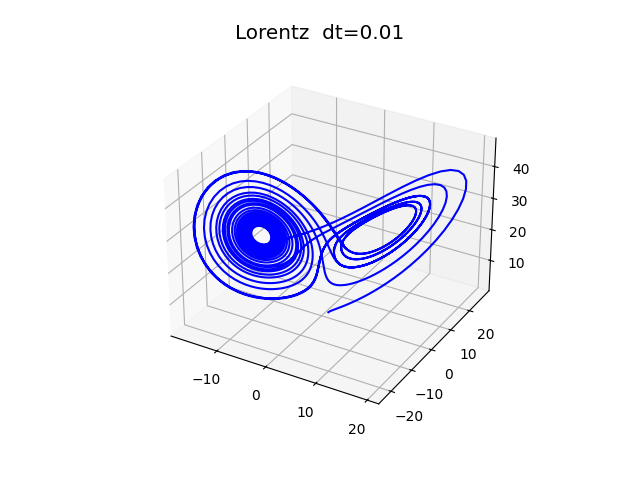

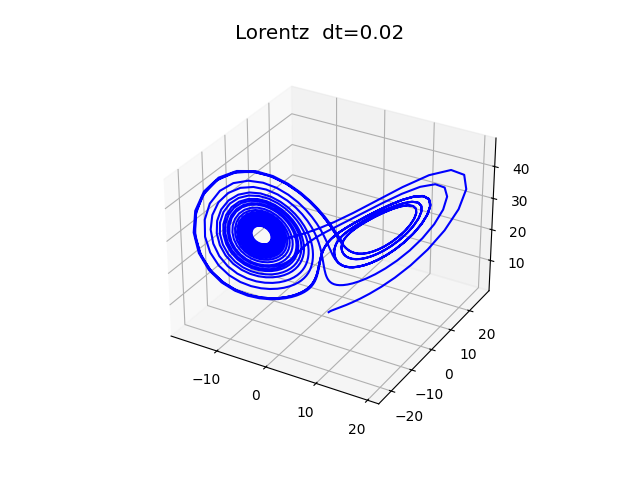

`Figure 16: Wykres z(x,y) układu Lorenza metodą scipy. dla kroków dt = {0.001, 0.01, 0.02} przy stałych parametrach`

`3. ŚREDNI BŁĄD APROKSYMACJI`

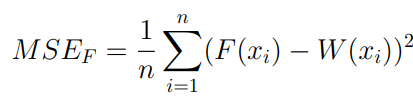

`Figure 17: Matematyczny wzór średniego błędu kwadratowego układu Lorenza [3]`

`Obliczymy średni błąd kwadratowy każdego sygnału za pomocą wzoru [Figure 17]:`

        def MSE(f1, f2, params):
        x = [f1(*params), f2(*params)]
        n = len(x[0])
        mse = 0
        for i in range(n):
            mse += pow(x[0][i] - x[1][i], exp=2)
        mse /= n
        print(mse)

`Figure 18: Realizacja średniego błędu kwadratowego w języku Python`

- `dt = 0.001`

Model Lorenza:        δx = 0.19591265      δy = 0.40308504      δz = 0.63858806
Model Lotki-Volterry: δx = 2.28737774e-04  δy = 08.76694501e-05

- `dt = 0.01`

Model Lorenza:        δx = 176.65041139    δy = 195.93848631    δz =  66.78692278
Model Lotki-Volterry: δx = 0.02694779      δy = 0.01025241

- `dt = 0.02`

Model Lorenza:        δx = 155.92353612    δy = 187.39329765    δz =  72.94273338
Model Lotki-Volterry: δx = 0.13041354      δy = 0.0490712

`Figure 19: Średnie błędy kwadratowe dla dt = {0.001, 0.01, 0.02} w języku Python`

#### `WNIOSKI`

`Obie metody wyliczania układów są algorytmami rozwiązywania równań różniczkowych, zatem spodziewać możemy się, że w zależności od doboru dyskretnego kroku czasowego, otrzymany wynik będzie jedynie przybliżeniem rozwiązania. Metoda odeint wykorzystuje algorytm lsoda, który dynamicznie dostosowywuje sposób podejścia do rozwiązania ODE (wybierając pomiędzy różnymi metodami rozwiązywania ODE takimi jak metoda Runge-Kutta), z tego powodu obserwujemy, że szybciej zbiega on do rzeczywistego rozwiązania niż metoda Eulera. Jest on również z tego powodu stosunkowo mniej wrażliwy na niewiekie zmiany dt dla większości układów niż algorytm Eulera. Wciąż jednak, wybór kroku czasowego dt jest znaczący, ponieważ nie dokonujemy dyskretyzacji modelu, a rekurencyjnego podejścia rozwiązania numerycznego, co sprawia, że błędy wynikające z doboru dt nakładają się wraz z każdą iteracją, co uwidacznia się dla średnich kwadratowych błędów aproksymacji.`

`LITERATURA`

`[1] J.D. Murray: Wprowadzenie do Biomatematyki. Warszawa: Wydawnictwo Naukowe PWN, 2006.`

`[2] Edward N. Lorenz: Deterministic Nonperiodic Flow. „J.Atmos.Sci.”. 20 (2), s. 130–141, 1963.`

`[3] Robert Perliński: Aproksymacja II Metody numeryczne.`